# Gram Schmidt Algorithm for QR decomposition.

Suppose we are given a matrix $A\in \Re^{n\times n} \;$ with columns vectors,  $a_1 ,a_{2\;} ,\ldotp \ldotp \ldotp ,a_{n\;} \in \Re^n \;$


$$A=\left\lbrack \begin{array}{cccc}
{\mathit{\mathbf{a}}}_1  & {\mathit{\mathbf{a}}}_2  & \ldotp \ldotp \ldotp  & {\mathit{\mathbf{a}}}_{\mathit{\mathbf{n}}\;} 
\end{array}\right\rbrack$$


rng(56) 

% create random vectors a1, a2, a3
a1 = rand(3,1)

a1 =    9.8419e-01
   3.3341e-01
   6.7370e-01


a2 = [0.5 1 0 ]';
a3 = rand(3,1);

% our matrix
A = [ a1 a2 a3] 

A =    9.8419e-01   5.0000e-01   1.9639e-01
   3.3341e-01   1.0000e+00   3.5445e-01
   6.7370e-01            0   8.1337e-01


Let's visualize the vectors and plot them

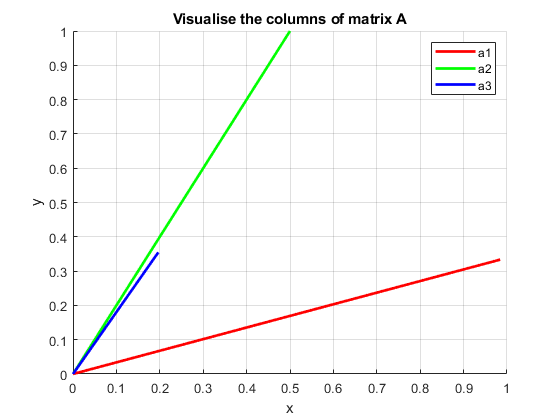

r = 0:0.05:1; 

figure(1)
hold on

plot3(r*a1(1),r*a1(2),r*a1(3), 'r','linewidth',2,'displayname','a1')
plot3(r*a2(1),r*a2(2),r*a2(3), 'g','linewidth',2,'displayname','a2')
plot3(r*a3(1),r*a3(2),r*a3(3), 'b','linewidth',2,'displayname','a3')
legend 
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualise the columns of matrix A')
hold off 

Are the columns of matrix A, orthogonal to each other? 

Q2. How can we check ?

% 

Our goal is to decompose the matrices in the following format,


$$\left\lbrack \begin{array}{cccc}
{\mathit{\mathbf{a}}}_1  & {\mathit{\mathbf{a}}}_2  & {\mathit{\mathbf{a}}}_3  & {\mathit{\mathbf{a}}}_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
{\mathit{\mathbf{q}}}_1  & {\mathit{\mathbf{q}}}_2  & {\mathit{\mathbf{q}}}_3  & {\mathit{\mathbf{q}}}_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
r_{11}  & r_{12}  & r_{13}  & r_{14} \\
 & r_{22}  & r_{23}  & r_{24} \\
 &  & r_{33}  & r_{34} \\
 &  &  & r_{44} 
\end{array}\right\rbrack$$


with ${\mathit{\mathbf{q}}}_i^{T\;} {\mathit{\mathbf{q}}}_i =1$. 

We want to find element of matrix $\textbf R$ and also make sure that the vectors $\textbf q_i$ have unit norm.

q1 = a1;  

r11 = norm(a1);
q1 = a1/r11;

% check the norm of q1.
normQ1 = norm(q1);

Q3. In the figure below ${\mathit{\mathbf{p}}}_{21\;}$ is the projection of ${\mathit{\mathbf{a}}}_2$ onto $q_1$, i.e.${\mathit{\mathbf{p}}}_{21\;} \equiv {\mathrm{proj}}_{{\mathit{\mathbf{a}}}_{1\;} } {\mathit{\mathbf{a}}}_2 \;$.

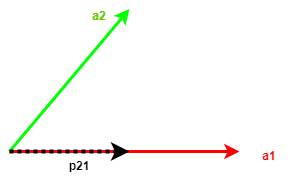

Find the expression for ${\mathit{\mathbf{p}}}_{21\;}$.

 
$$\textbf p_{21} = \frac{ \textbf q_1^T  \textbf a_2}{ \textbf q_1^T \textbf q_1}   \textbf q_1$$


Since $\textbf q_1^T \textbf q_1=1$,  =>$\textbf p_{21} = ( \textbf q_1^T  \textbf a_2)  \textbf q_1$

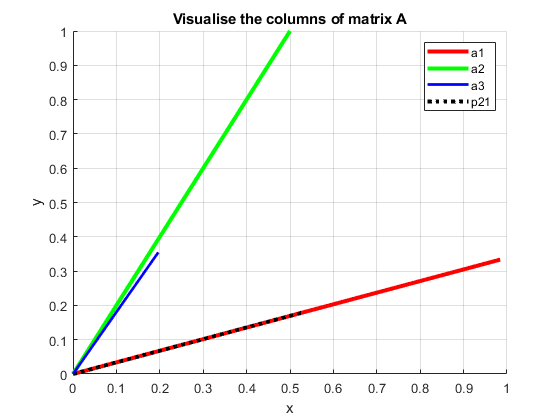

figure(2)


p2 = (q1'*a2)*q1;
hold on

plot3(r*a1(1),r*a1(2),r*a1(3), 'r','linewidth',3,'displayname','a1')
plot3(r*a2(1),r*a2(2),r*a2(3), 'g','linewidth',3,'displayname','a2')
 plot3(r*a3(1),r*a3(2),r*a3(3), 'b','linewidth',2,'displayname','a3')
plot3(r*p2(1),r*p2(2),r*p2(3), 'k:','linewidth',3,'displayname','p21')
legend 
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualise the columns of matrix A')
hold off

 Q4. Now we know the projection ${\mathit{\mathbf{p}}}_{21\;}$( projection of ${\mathit{\mathbf{a}}}_2$ onto $q_1$),  find the component of $\textbf a_2$ orthogonal to $\textbf q_1$.

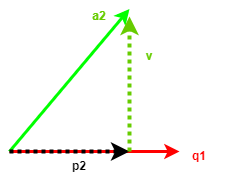

Sol. Using vector law of additon,


$$\textbf p_{21} +\textbf v = \textbf a_2$$



$$=> \textbf v= \textbf a_2 - \textbf p_{21}$$



$$=> \textbf v = \textbf a_2 - ( \textbf q_1^T  \textbf a_2)  \textbf q_1$$



$$\textbf q_2 = \frac{\textbf v}{norm(\textbf v)}$$


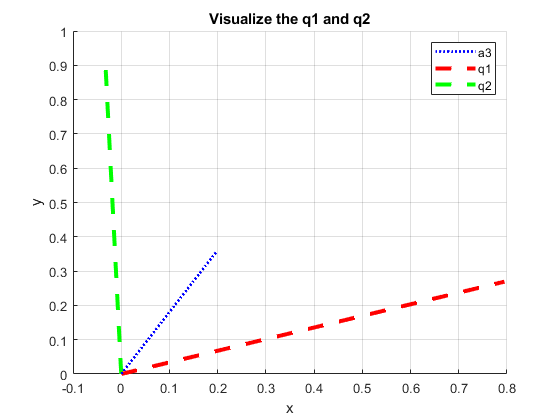

r11 = norm(a1);
q1 = a1/r11;

%---------------------------------------------------

p2 = (q1'*a2)*q1; % projection of a2 on q1

r12 = (q1'*a2);
v = a2 -r12*q1;

r22 = norm(v);
q2 = v/r22;


figure(3)
hold on

plot3(r*a3(1),r*a3(2),r*a3(3), 'b:','linewidth',2,'displayname','a3')
plot3(r*q1(1),r*q1(2),r*q1(3), 'r--','linewidth',3,'displayname','q1')
plot3(r*q2(1),r*q2(2),r*q2(3), 'g--','linewidth',3,'displayname','q2')
legend 
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualize the q1 and q2')
hold off

Q5:  Which of the following is true:

The $\textbf q_2$  is orthogonal to the :

        a.  vector/column $\textbf a_1$only

        b.  vector/column $\textbf a_2$ only

        c.   vectors/columns $\textbf a_1$ and $\textbf a_2$

        d.   Vectors/columns $\textbf a_1$, $\textbf q_1$ and $\textbf p_{21}$

Q6. Write  the expression for the following,

a. $proj_{\textbf q_1} \textbf a_3$

b. $proj_{\textbf q_2} \textbf a_3$

Sol.


$$proj_{\textbf q_1} \textbf a_3 = \frac{ \textbf a_3^T  \textbf q_1}{ \textbf q_1^T \textbf q_1}   \textbf q_1$$



$$proj_{\textbf q_2} \textbf a_3 = \frac{ \textbf a_3^T  \textbf q_2}{ \textbf q_2^T \textbf q_2}   \textbf q_2$$


Q7 . Find the component of $\textbf a_3$ orthogonal to $\textbf q_1$and $\textbf q_2$.

Sol .

Use the vector law of addition for 3 vectors,


$$\textbf q_3  = proj_{\textbf q_1} \textbf a_3 - proj_{\textbf q_2} \textbf a_3$$



$$=> \textbf v = \textbf a_3 - \frac{ \textbf q_1^T  \textbf a_3}{ \textbf q_1^T \textbf q_1}   \textbf q_1
-
 \frac{ \textbf q_2^T  \textbf a_3}{ \textbf q_2^T \textbf q_2}   \textbf q_2$$


but since $\textbf q_1^T \textbf q_1=1$ and $\textbf q_2^T \textbf q_2=1$


$$=> \textbf v= \textbf a_3 - ( \textbf a_3^T  \textbf q_1) \textbf a_1
-
 ( \textbf a_3^T  \textbf q_1)  \textbf q_2$$


All the equatons thus far:

 **Column 1 of A: **   

    
$$v = a_1$$


    
$$r_{11} = norm(v)$$


    
$$q_1 = \frac{v}{r_{11}}$$


 **Column 2 of A: **   

    
$$r_{12} = q_1^Ta_2$$


    
$$v = a_2 - r_{12}\; q_1$$


    
$$r_{22} = norm(v)$$


    
$$q_2= \frac{v}{r_{22}}$$


 **Column 3 of A: **   

    
$$r_{13} = q_1^Ta_3$$


    
$$r_{23} = q_2^Ta_3$$


    
$$v = a_2 - r_{13}\; q_1 - r_{23} \;q_2$$


    
$$r_{33} = norm(v)$$


    
$$q_3= \frac{v}{r_{33}}$$


**Column 4 of A: **   

    
$$r_{14} = q_1^Ta_4$$


    
$$
r_{24} = q_2^Ta_4$$


    
$$r_{34} = q_3^Ta_4$$


    
$$v = a_2 - r_{14}\; q_1 - r_{24} \;q_2 - r_{34}\; q_4$$


    
$$r_{44} = norm(v)$$


    
$$q_4= \frac{v}{r_{44}}$$


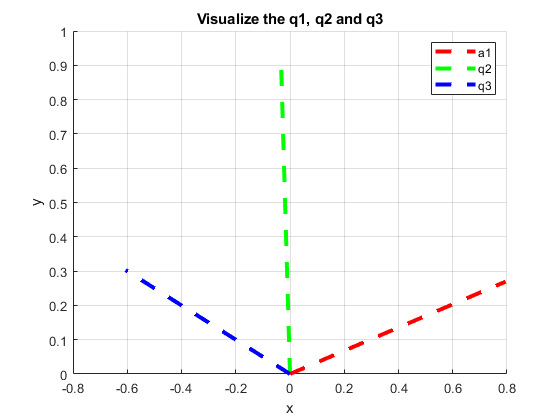

% first column of  A
r11 = norm(a1);
q1 = a1/r11;

% second column of A
p2 = (q1'*a2)*q1; % projection of a2 on q1

r12 = (q1'*a2);
v = a2 -r12*q1;

r22 = norm(v);
q2 = v/r22;

% third column of A
r13 = (q1'*a3);
r23 = (q2'*a3);
v = a3 -r13*q1 - r23*q2;

r33 = norm(v);
q3 =  v/r33;

figure(4)
hold on


plot3(r*q1(1),r*q1(2),r*q1(3), 'r--','linewidth',3,'displayname','a1')
 plot3(r*q2(1),r*q2(2),r*q2(3), 'g--','linewidth',3,'displayname','q2')
plot3(r*q3(1),r*q3(2),r*q3(3), 'b--','linewidth',3,'displayname','q3')

legend 
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualize the q1, q2 and q3')
hold off

## Example 2:  Classical Gram-Schmidt is susceptible to rounding errors.

r = 0:0.05:1; 

A =  [ 1        1       1 ;
       1e-16    0       0 ;
       0       1e-16    0];
   
       
%    A  = hilb(3)
a1 =  A(:,1);
a2 =  A(:,2);
a3 =   A(:,3);
% first column of  A
r11 = norm(a1);
q1 = a1/r11;

% second column of A
p2 = (q1'*a2)*q1; % projection of a2 on q1

r12 = (q1'*a2);
v = a2 -r12*q1;

r22 = norm(v);
q2 = v/r22;

% third column of A
r13 = (q1'*a3);
r23 = (q2'*a3);
v = a3 -r13*q1 - r23*q2;

r33 = norm(v);
q3 =  v/r33;


figure(5)
hold on


plot3(r*a1(1),r*a1(2),r*a1(3), 'r:','linewidth',3,'displayname','a1')
 plot3(r*a2(1),r*a2(2),r*a2(3), 'g:','linewidth',3,'displayname','a2')
plot3(r*a3(1),r*a3(2),r*a3(3), 'b:','linewidth',3,'displayname','a3')
legend 

ans =   Legend (a1, a2, a3, a1, a2, a3) with properties:

         String: {'a1'  'a2'  'a3'  'a1'  'a2'  'a3'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7702 0.6567 0.1161 0.2440]
          Units: 'normalized'

  Show all properties


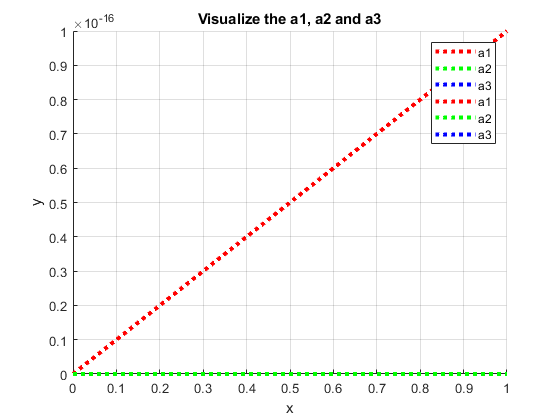

grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualize the a1, a2 and a3')
hold off

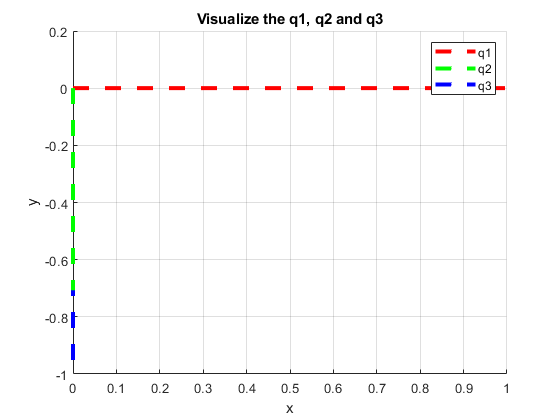



figure(6)
hold on


plot3(r*q1(1),r*q1(2),r*q1(3), 'r--','linewidth',3,'displayname','q1')
 plot3(r*q2(1),r*q2(2),r*q2(3), 'g--','linewidth',3,'displayname','q2')
plot3(r*q3(1),r*q3(2),r*q3(3), 'b--','linewidth',3,'displayname','q3')

legend 
grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualize the q1, q2 and q3')
hold off

## Modifed Gram-Schmidt 

Initialise orthogonal vectors of **Q** as columns of **A**


$$q_1 = a_1,   q_2 = a_2, q_3 = a_3, q_4= a_4$$
 

** Column 1 of A: **   

    
$$v = a_1$$


    
$$r_{11} = norm(v)$$


    
$$q_1 = \frac{v}{r_{11}}$$


  Now we have all the information that is required to compute the first row of the components of matrix R.

    
$$r_{12} = q_1^Tq_2$$


    
$$r_{13} = q_1^Tq_3$$


    
$$r_{14} = q_1^Tq_4$$


 We can also subtract the projection of vector q1  from q2, q3 and q4

   
$$q_2 = q_2 - r_{12}\; q_1$$


   
$$q_3 = q_3 - r_{13}\; q_1$$


   
$$q_4 = q_4 - r_{14}\; q_1$$


 **Column 2 of A: **   

    
$$r_{22} = norm(q_2)$$


    
$$q_2= \frac{q_2}{r_{22}}$$


    We  have all the information that is required to compute the second row of the components of matrix R.

    
$$r_{23} = q_2^T q_3$$


    
$$
r_{24} = q_2^Ta_4$$


    Subtract the projection of vector q2 from q3 and q4

     
$$q_3 = q_3 - r_{23}\; q_2$$


     
$$q_4 = q_4 - r_{24}\; q_2$$


 **Column 3 of A: **   

    
$$r_{33} = norm(q_3)$$


    
$$q_3= \frac{q_3}{r_{33}}$$


    compute the third row of the components of matrix R.

    
$$r_{34} = q_3^T q_4$$


 Subtract the projection of vector q3  from q4

     
$$q_4 = q_4 - r_{34}\; q_3$$


**Column 4 of A: **   

    
$$r_{44} = norm(q_4)$$


   
$$q_4= \frac{q_4}{r_{44}}$$


r = 0:0.05:1; 

A =  [ 1      1    1 ;
       1e-16  0    0 ;
       0       1e-16 0];
%    A  = hilb(4)
a1 =  A(:,1);
a2 =  A(:,2);
a3 =   A(:,3);
% a4 =   A(:,4);
% initialise columns of Q as columns of A
q1 = a1;
q2 = a2;
q3 = a3;
% q4 = a4;

% first column of  A
r11 = norm(a1);
q1 = a1/r11;

r12 = (q1'*q2);
q2 = q2 - r12*q1;

r13= (q1'*q3);
q3 = q3 - r13*q1;

% r14= (q1'*a4);
% q4 = q4 - r14*q1;


% second column of A
r22 = norm(q2)

r22 = 1.4142e-16

q2= q2/r22;

r23 = (q2'*q3);
q3  = q3 - r23*q2;

% r24 = (q2'*q4);
% q4  = q4 - r24*q2;

% third column of A

r33 = norm(q3);
q3 =q3/r33

q3 =          0
   -0.7071
   -0.7071



% r34 = (q3'*q4);
% q4  = q4 - r34*q4;


% % fourth column of A
% 
% r44 = norm(q4);
% q4 =q4/r44



figure(7)
hold on


plot3(r*q1(1),r*q1(2),r*q1(3), 'r--','linewidth',3,'displayname','a1')
 plot3(r*q2(1),r*q2(2),r*q2(3), 'g--','linewidth',3,'displayname','q2')
plot3(r*q3(1),r*q3(2),r*q3(3), 'b--','linewidth',3,'displayname','q3')

legend 

ans =   Legend (a1, q2, q3, a1, q2, q3) with properties:

         String: {'a1'  'q2'  'q3'  'a1'  'q2'  'q3'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7702 0.6567 0.1161 0.2440]
          Units: 'normalized'

  Show all properties


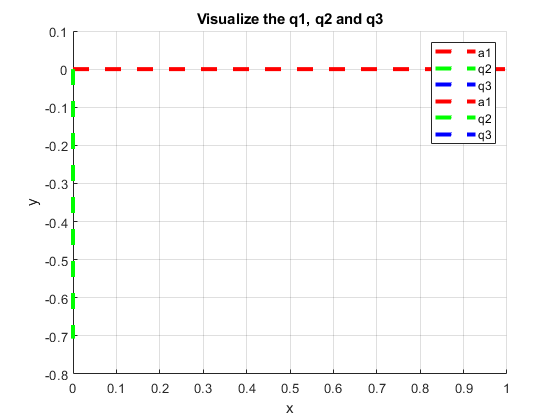

grid on
xlabel('x')
ylabel('y')
zlabel('z')
title('Visualize the q1, q2 and q3')
hold off